clc;
clear;

data = 'free_space';
contact = 'no_contact';
test_folder = 'test';
rnn = 'lstm';
network = '_seal_pred_filtered_torque_glove_1_15.csv';

arm = 'psm1_mary';

%loss = 0;
loss = [0,0,0,0];

%for file = 0:3
file = 0;
exp = ['exp',num2str(file)];

% joint_path = ['../../glove_jan_10/', test_folder, '/', arm, '/', data, '/joints/'];
%       torque_path = ['../../glove_jan_10/', test_folder, '/', arm, '/', data, '/', 'lstm', network];
      
% joint_path = ['../../../simon_trocar_feb_27/test', '/joints/'];
% fs_pred_torque_path = ['../../../simon_trocar_feb_27/test', '/TO_free_comp_model_pred.csv'];
% troc_corr_path = ['../../../simon_trocar_feb_27', '/filtered_corrected_torque_prediction.csv'];

joint_path = ['../../simon_trocar_mar_6/test_free_trocar', '/joints/'];
fs_pred_torque_path = ['../../simon_trocar_mar_6/test_free_trocar', '/TO_cont_model_pred.csv'];
troc_corr_path = ['../../simon_trocar_mar_6/test_free_trocar', '/filtered_corrected_torque_prediction.csv'];
      

joint_data = readmatrix([joint_path, 'interpolated_all_joints_CUT.csv']);
fs_pred_data = readmatrix(fs_pred_torque_path);
troc_corr_data = readmatrix(troc_corr_path);

measured_torque = joint_data(:,14:16);
fs_pred_torque = fs_pred_data(:,1:3);

troc_cor = troc_corr_data(:,2:4);

% loss(file+1) = mean(sqrt(mean((measured_torque(1:length(troc_cor),:) - fs_pred_torque).^2)));
loss_joint1_troc = mean(sqrt(mean((measured_torque(1:length(troc_cor),1) - troc_cor(:,1)).^2)));
loss_joint2_troc = mean(sqrt(mean((measured_torque(1:length(troc_cor),2) - troc_cor(:,2)).^2)));
loss_joint3_troc = mean(sqrt(mean((measured_torque(1:length(troc_cor),3) - troc_cor(:,3)).^2)));
loss_joint1_fs = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),1) - fs_pred_torque(:,1)).^2)));
loss_joint2_fs = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),2) - fs_pred_torque(:,2)).^2)));
loss_joint3_fs = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),3) - fs_pred_torque(:,3)).^2)));
loss_joint4 = mean(sqrt(mean((joint_data(1:length(troc_cor),17) - fs_pred_data(1:length(troc_cor),5) + troc_corr_data(:,5)).^2)));
loss_joint5 = mean(sqrt(mean((joint_data(1:length(troc_cor),18) - fs_pred_data(1:length(troc_cor),6) + troc_corr_data(:,6)).^2)));
loss_joint6 = mean(sqrt(mean((joint_data(1:length(troc_cor),19) - fs_pred_data(1:length(troc_cor),7) + troc_corr_data(:,7)).^2)));

[minSix, maxSix] = bounds(measured_torque(1:length(troc_cor),1));
boundX = abs(maxSix - minSix)

boundX = 2.7590

[minSiy, maxSiy] = bounds(measured_torque(1:length(troc_cor),2));
boundY = abs(minSiy - maxSiy)

boundY = 4.7532

[minSiz, maxSiz] = bounds(measured_torque(1:length(troc_cor),3));
boundZ = abs(maxSiz - minSiz)

boundZ = 4.5445


loss_x_nrmse = loss_joint1_troc/boundX

loss_x_nrmse = 0.0739

loss_y_nrmse = loss_joint2_troc/boundY

loss_y_nrmse = 0.0613

loss_z_nrmse = loss_joint3_troc/boundZ

loss_z_nrmse = 0.0980

loss_x_wo_corr_nrmse = loss_joint1_fs/boundX

loss_x_wo_corr_nrmse = 0.1371

loss_y_wo_corr_nrmse = loss_joint2_fs/boundY

loss_y_wo_corr_nrmse = 0.0736

loss_z_wo_corr_nrmse = loss_joint3_fs/boundZ

loss_z_wo_corr_nrmse = 0.0986

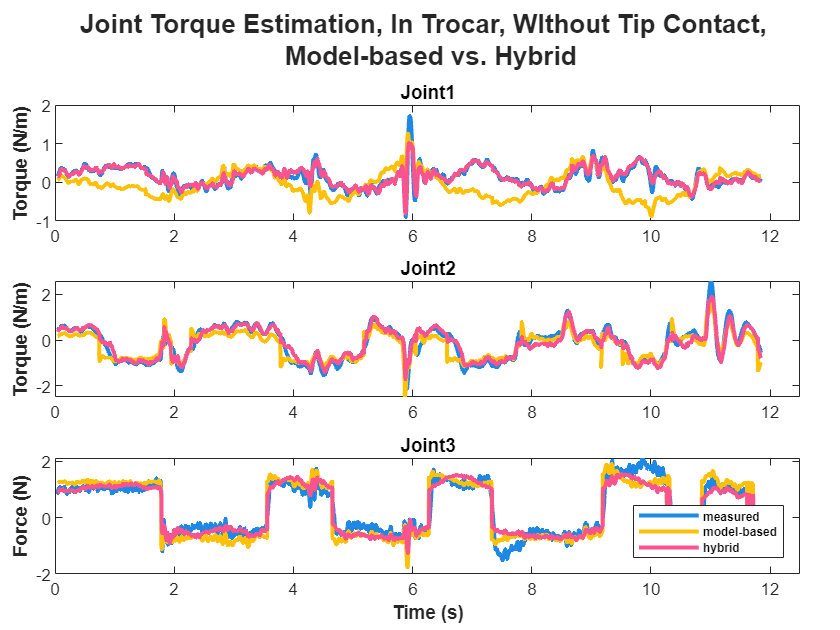



meas_sub_fs =  fs_pred_torque(1:length(troc_cor),:);

meas_sub_fs_corr =  troc_cor;

figure()
tcl = tiledlayout(3,1,'TileSpacing','Compact','Padding','Compact');

title(tcl, sprintf('Joint Torque Estimation, In Trocar, WIthout Tip Contact, \n Model-based vs. Hybrid'),...
    'FontWeight','bold')


nexttile
plot(troc_corr_data(40-39:2400-39, 1), measured_torque(40:2400,1), 'color', '#1E88E5', 'LineWidth', 2)
hold on
title(sprintf('Joint1'));
plot(troc_corr_data(40-39:2400-39, 1), meas_sub_fs(40:2400,1), 'color', '#FFC107', 'LineWidth', 2)
plot(troc_corr_data(40-39:2400-39, 1), meas_sub_fs_corr(30:2400-10,1), 'color', '#F95390', 'LineWidth', 2)
xlim([0 12.5])
% xlabel('Time (s)')
ylabel('Torque (N/m)', 'FontWeight','bold')



hold off

nexttile
plot(troc_corr_data(40-39:2400-39, 1), measured_torque(40:2400,2), 'color', '#1E88E5', 'LineWidth', 2)
hold on
title(sprintf('Joint2'))
plot(troc_corr_data(40-39:2400-39, 1), meas_sub_fs(40:2400,2), 'color', '#FFC107', 'LineWidth', 2)
plot(troc_corr_data(40-39:2400-39, 1), meas_sub_fs_corr(30:2400-10,2), 'color', '#F95390', 'LineWidth', 2)
% xlabel('Time (s)')
ylabel('Torque (N/m)', 'FontWeight','bold')
xlim([0 12.5])
hold off

nexttile
plot(troc_corr_data(40-39:2400-39, 1), measured_torque(40:2400,3), 'color', '#1E88E5', 'LineWidth', 2)
hold on
title(sprintf('Joint3'))
plot(troc_corr_data(40-39:2400-39, 1), meas_sub_fs(40:2400,3), 'color', '#FFC107', 'LineWidth', 2)
plot(troc_corr_data(40-39:2400-39, 1), meas_sub_fs_corr(30:2400-10,3), 'color', '#F95390', 'LineWidth', 2)
xlim([0 12.5])
xlabel('Time (s)', 'FontWeight','bold')
ylabel('Force (N)', 'FontWeight','bold')

legend('measured', 'model-based', 'hybrid','Location', 'southeast', 'fontsize', 6, 'FontWeight','bold') 



% nexttile
% plot(troc_corr_data(:, 1), measured_torque(1:length(troc_corr_data),1), 'b', 'LineWidth', 2)
% hold on
% title(sprintf('Joint1'));
% plot(troc_corr_data(:, 1), meas_sub_fs(1:length(troc_corr_data),1), 'g', 'LineWidth', 2)
% plot(troc_corr_data(:, 1), meas_sub_fs_corr(1:length(troc_corr_data),1), 'r', 'LineWidth', 2)
% % xlim([0 12.5])
% xlabel('Time (s)')
% ylabel('Torque (N/m)')
% 
% legend('measured', 'meas-fs', 'meas-(fs-cor)','Location', 'northeast')
% 
% hold off
% 
% nexttile
% plot(troc_corr_data(:, 1), measured_torque(1:length(troc_corr_data),2), 'b', 'LineWidth', 2)
% hold on
% title(sprintf('Joint2'))
% plot(troc_corr_data(:, 1), meas_sub_fs(1:length(troc_corr_data),2), 'g', 'LineWidth', 2)
% plot(troc_corr_data(:, 1), meas_sub_fs_corr(1:length(troc_corr_data),2), 'r', 'LineWidth', 2)
% xlabel('Time (s)')
% ylabel('Torque (N/m)')
% % xlim([0 12.5])
% hold off
% 
% 
% 
% nexttile
% plot(troc_corr_data(:, 1), measured_torque(1:length(troc_corr_data),3), 'b', 'LineWidth', 2)
% hold on
% title(sprintf('Joint3'))
% plot(troc_corr_data(:, 1), meas_sub_fs(1:length(troc_corr_data),3), 'g', 'LineWidth', 2)
% plot(troc_corr_data(:, 1), meas_sub_fs_corr(1:length(troc_corr_data),3), 'r', 'LineWidth', 2)
% % xlim([0 12.5])
% xlabel('Time (s)')
% ylabel('Force (N)')
% 
% 
% hold off

% nexttile
% plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,17), 'b')
% hold on
% title('joint 4')
% plot(torque_data(:, 1), torque_data(:,5), 'r')
% 
% nexttile
% plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,18), 'b')
% hold on
% title('joint 5')
% plot(torque_data(:, 1), torque_data(:,6), 'r')
% 
% nexttile
% plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,19), 'b')
% hold on
% title('joint 6')
% plot(torque_data(:, 1), torque_data(:,7), 'r')
% legend('measured', 'predicted')
